clear
% Load and define all examples
x1all = load('class_1','-ascii');
x2all = load('class_2','-ascii');
x3all = load('class_3','-ascii');

xAll = [x1all;
        x2all;
        x3all];


% Define constants for training and saving 
nSamples = length(x1all); %50
nTraining = 30;
nTests = nSamples - nTraining;
nClasses = 3;
nFeatures = 4;

iters = 350; %num of iteration when training W
alpha_test_array = [0.01 0.0075 0.0025 0.005]; 


% Define the true classification for xAll
targets = [kron(ones(nTraining,1), [1 0 0]);
           kron(ones(nTraining,1), [0 1 0]); 
           kron(ones(nTraining,1), [0 0 1])];


% Chose case to run
casenr = 5;
saveAll = 1;

% Save names for plots
IrisHistogram_filename = "./Figures/Iris_Histogram.png";
MSE_progression_filename = "./Figures/MSE_progression_case" + num2str(casenr) + ".png";
ErrorRate_progression_filename = "./Figures/ErrorRate_progression_case" + num2str(casenr) + ".png";
CCTraining_filename = "./Figures/ConfusionChartTraining_case" + num2str(casenr) + ".png";
CCTest_filename = "./Figures/ConfusionChartTest_case" + num2str(casenr) + ".png";

switch casenr
    case 1 %first 30 samples for training
        xTraining = [x1all(1:nTraining, :);
                     x2all(1:nTraining, :);
                     x3all(1:nTraining, :)];
        
        xTests  = [x1all(nTraining+1:end, :);
                  x2all(nTraining+1:end, :);
                  x3all(nTraining+1:end, :)];

    case 2 % last 30 samples for training
        xTraining = [x1all(nTests+1:end, :);
                     x2all(nTests+1:end, :);
                     x3all(nTests+1:end, :)];
        
        xTests  = [x1all(1:nTests, :);
                   x2all(1:nTests, :);
                   x3all(1:nTests, :)];
        iters = 400;
    case 3 % Sepal witdh removed from features (indx 2)
        xAll(:,2) = [];

        xTraining = [x1all(1:nTraining, :);
                     x2all(1:nTraining, :);
                     x3all(1:nTraining, :)];
        
        xTests  = [x1all(nTraining+1:end, :);
                  x2all(nTraining+1:end, :);
                  x3all(nTraining+1:end, :)];

        xTraining(:,2) = [];
        xTests(:,2)  = [];
        nFeatures = 3;
        alpha_test_array = [0.01 0.0075 0.005 0.006];
        iters = 900;
    case 4 % Sepal witdh and length removed from features (indx 1, 2)
        xAll(:,1:2) = [];

        xTraining = [x1all(1:nTraining, :);
                     x2all(1:nTraining, :);
                     x3all(1:nTraining, :)];
        
        xTests  = [x1all(nTraining+1:end, :);
                  x2all(nTraining+1:end, :);
                  x3all(nTraining+1:end, :)];

        xTraining(:,1:2) = [];
        xTests(:,1:2)  = [];
        nFeatures = 2;
        alpha_test_array = [0.006 0.0075 0.01 0.015];
        iters = 6500;
    case 5 % Sepal witdh and length and petal width removed from features (indx 1, 2, 4)
        xAll = xAll(:,3);
        
        xTraining = [x1all(1:nTraining, 3);
                     x2all(1:nTraining, 3);
                     x3all(1:nTraining, 3)];
        
        xTests  = [x1all(nTraining+1:end, 3);
                  x2all(nTraining+1:end, 3);
                  x3all(nTraining+1:end, 3)];

        nFeatures = 1;
        alpha_test_array = [0.15 0.0075 0.01];
        iters = 5000;
end



xTraining_aug = [ ones(nTraining*nClasses,1) xTraining];

% To be used when creating the confusion chart
TrueClasses_training = [ones(1,nTraining), 2*ones(1,nTraining), 3*ones(1,nTraining)]; % 'setosa','versicolor','virginica' 
TrueClasses_test =  [ones(1,nTests), 2*ones(1,nTests), 3*ones(1,nTests)];


Error_rate_training_vals = zeros(1, iters);
Error_rate_test_vals = zeros(1, iters);

MSE_vals = zeros(1,iters);
MSE_indx = 1;
tic
for alpha = alpha_test_array    
    
    W_k = zeros(nClasses,nFeatures+1); 
    for i = 1:iters
        [MSE_k, grad_W_MSE] = grad_MSE(W_k, xTraining_aug,targets);
        
        MSE_vals(MSE_indx,i) = MSE_k;

        % Calculate error rate
        Error_rate_training_vals(1,i) = computeErrorRate(W_k, xTraining, TrueClasses_training, nTraining*nClasses);
        Error_rate_test_vals(1,i) = computeErrorRate(W_k, xTests, TrueClasses_test, nTests*nClasses);
        

        W_k = W_k - alpha * grad_W_MSE;
    
    end
       

    MSE_indx = MSE_indx + 1;
    

end 
toc

Elapsed time is 3.591967 seconds.


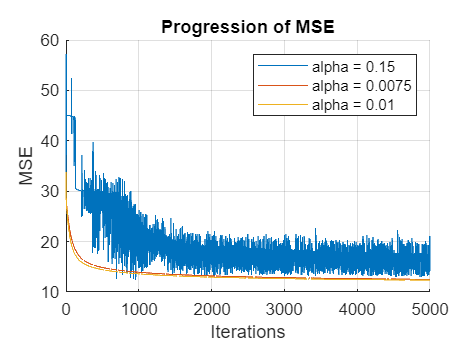



nexttile;
hold on;
grid on;
xlabel("Iterations");
ylabel("MSE");
title("Progression of MSE");
for r = 1:MSE_indx-1
    plot(1:iters, MSE_vals(r,:));
    Legend{r} = sprintf("alpha = %g", alpha_test_array(r));
end
legend(Legend);
hold off

if saveAll == 1
    saveas(gca, MSE_progression_filename)
end

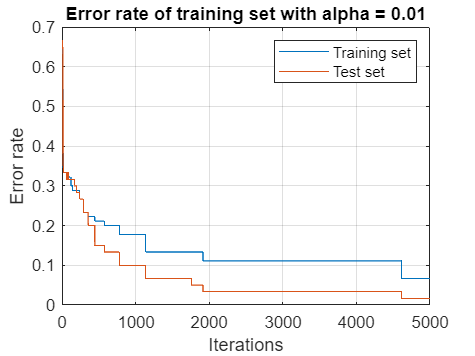



figure(2);
plot(1:iters, Error_rate_training_vals, 1:iters, Error_rate_test_vals);
xlabel("Iterations");
ylabel("Error rate");
legend("Training set", "Test set")
title( sprintf("Error rate of training set with alpha = %g", alpha));
grid on;

if saveAll == 1
    saveas(gca, ErrorRate_progression_filename)
end

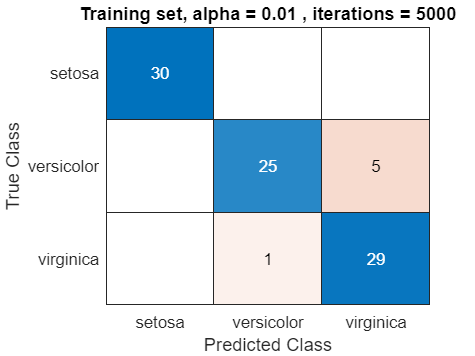


W_trained = W_k;

confmTraining = zeros(nClasses);
confmTest = zeros(nClasses);


% groupClasses = zeros(1,nTraining*nClasses); % 'setosa','versicolor','virginica' 
% groupChat = zeros(1,nTraining*nClasses);

for i = 1:3 %True class
    
    xClass = xAll((i-1)*nSamples+1:i*nSamples ,:);
    for k = 1:nSamples
        x = xClass(k,:).';    
        j = LinClassify(W_trained, x); % Result from classifier
           
        % Save in correct confusion matrix
        if k <= nTraining
            confmTraining(i,j) = confmTraining(i,j) + 1;
            % groupClasses(1,(i-1)*nTraining+k) = i;
            % groupChat(1,(i-1)*nTraining+k) = j;

        else
            confmTest(i,j) = confmTest(i,j) + 1;
        end
    end 
end

% c = confusionmat(groupClasses, groupChat )

training_title = sprintf("Training set, alpha = %g , iterations = %d", alpha, iters);
confusionchart(confmTraining, {'setosa','versicolor','virginica' }, 'Title',training_title)

if saveAll == 1
    saveas(gca, CCTraining_filename)
end

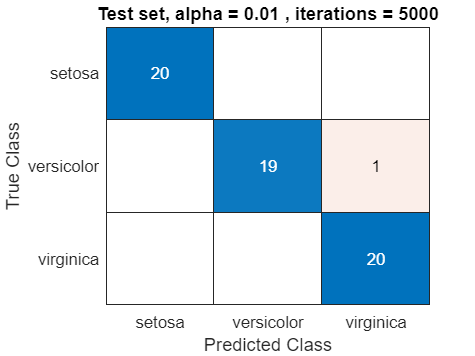



test_title = sprintf("Test set, alpha = %g , iterations = %d", alpha, iters);
confusionchart(confmTest, {'setosa','versicolor','virginica' }, 'Title',test_title)
if saveAll == 1
    saveas(gca, CCTest_filename)
end


error_rate_training = computeErrorRate(W_trained, xTraining, TrueClasses_training, nTraining*nClasses); %Accuracy of training set

error_rate_test = computeErrorRate(W_trained, xTests, TrueClasses_test, nTests*nClasses); %Accuracy of test set


confmTraining

confmTraining =     30     0     0
     0    25     5
     0     1    29


disp("Error rate for traingin set: "); error_rate_training

Error rate for traingin set: 


error_rate_training = 0.0667


confmTest

confmTest =     20     0     0
     0    19     1
     0     0    20


disp("Error rate for test set: "); error_rate_test

Error rate for test set: 


error_rate_test = 0.0167

## Feature histogram

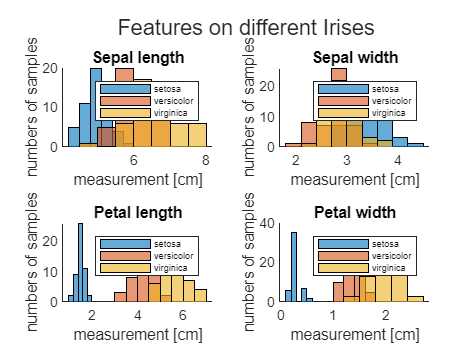


Layout = tiledlayout(2,2);

LegendFontsize = 5.5;

nexttile
hold on
histogram(x1all(:,1));
histogram(x2all(:,1));
histogram(x3all(:,1));
hold off
xlabel("measurement [cm]");
ylabel("numbers of samples")
legend('setosa','versicolor','virginica','FontSize',LegendFontsize)
title("Sepal length")


nexttile
hold on
histogram(x1all(:,2));
histogram(x2all(:,2));
histogram(x3all(:,2));
hold off
xlabel("measurement [cm]");
ylabel("numbers of samples")
legend('setosa','versicolor','virginica','FontSize',LegendFontsize)
title("Sepal width")

nexttile
hold on
histogram(x1all(:,3));
histogram(x2all(:,3));
histogram(x3all(:,3));
hold off
xlabel("measurement [cm]");
ylabel("numbers of samples")
legend('setosa','versicolor','virginica','FontSize',LegendFontsize)
title("Petal length")

nexttile
hold on
histogram(x1all(:,4));
histogram(x2all(:,4));
histogram(x3all(:,4));
hold off
xlabel("measurement [cm]");
ylabel("numbers of samples")
legend('setosa','versicolor','virginica','FontSize',LegendFontsize)
title("Petal width")


title(Layout, "Features on different Irises")
if saveAll == 1
    saveas(gca, IrisHistogram_filename)
end

function error_rate = computeErrorRate(W, x_all, trueClass,size)
    
    correct_pred = 0;
    for i = 1:length(trueClass)
        correct_pred = correct_pred + (trueClass(i) == LinClassify(W,x_all(i,:).'));
    end
   error_rate =  1 - correct_pred / size;
end


function class = LinClassify(W, x)
    g = W * [1; x];
    [~ , index] = max(g);
    class = index;
end


function [MSE, grad_MSE] = grad_MSE(W, xTraining_aug, targets)
    
    MSE = 0;
    grad_MSE = zeros(3,length(xTraining_aug(1,:)));
    for k = 1:length(xTraining_aug)
        
        t_k = targets(k, :).';
        x_k = xTraining_aug(k, :).';
        z_k = W*x_k;
        g_k = sigmoid(z_k);
        grad_MSE = grad_MSE + ((g_k-t_k) .* g_k .* (ones(3,1)-g_k)) * x_k.';
        MSE = MSE + 1/2 * (g_k-t_k).' * (g_k-t_k);
    end

    
end


function g = sigmoid(z)
    g = 1 ./ (1 + exp(-z));
end